## Step 0 | Identify videos

% Use this to identify dimensions: 
% Example
% >>PlaySeqFile('24-13')
% 20210824-20-24-13.000.seq
% 't range is [330.00 330.10] (seconds)'
%  'Size of this video 20210824-20-24-13.000.seq is 
%       [ 900 1104]' % (This is the side video)
% >>PlaySeqFile('24-16')
% 20210824-20-24-16.000.seq
%   't range is [330.00 330.10] (seconds)'
%     'Size of this video 20210824-20-24-16.000.seq is 
%       [ 550  752]'
%[file_names, names] = Spikes.Videos.getVideoInfos([900 1104], [550 752]);
[file_names, names] = Spikes.Videos.getVideoInfos([900 1000], [704 880]);
disp(file_names)

    {'20251127-15-13-40.000.seq'}    {'20251127-15-13-42.000.seq'}    {'20251127-15-53-34.000.seq'}    {'20251127-15-53-36.000.seq'}



[names,idx] = sort(names);
file_names = file_names(idx);
disp(names)

    {'SideView_20251127-15-13-40'}    {'SideView_20251127-15-53-34'}    {'TopView_20251127-15-13-42'}    {'TopView_20251127-15-53-36'}



## Step 1 | Extract frame times and ROI amplitude (for alignment)

ans = 'Please select region of interests'

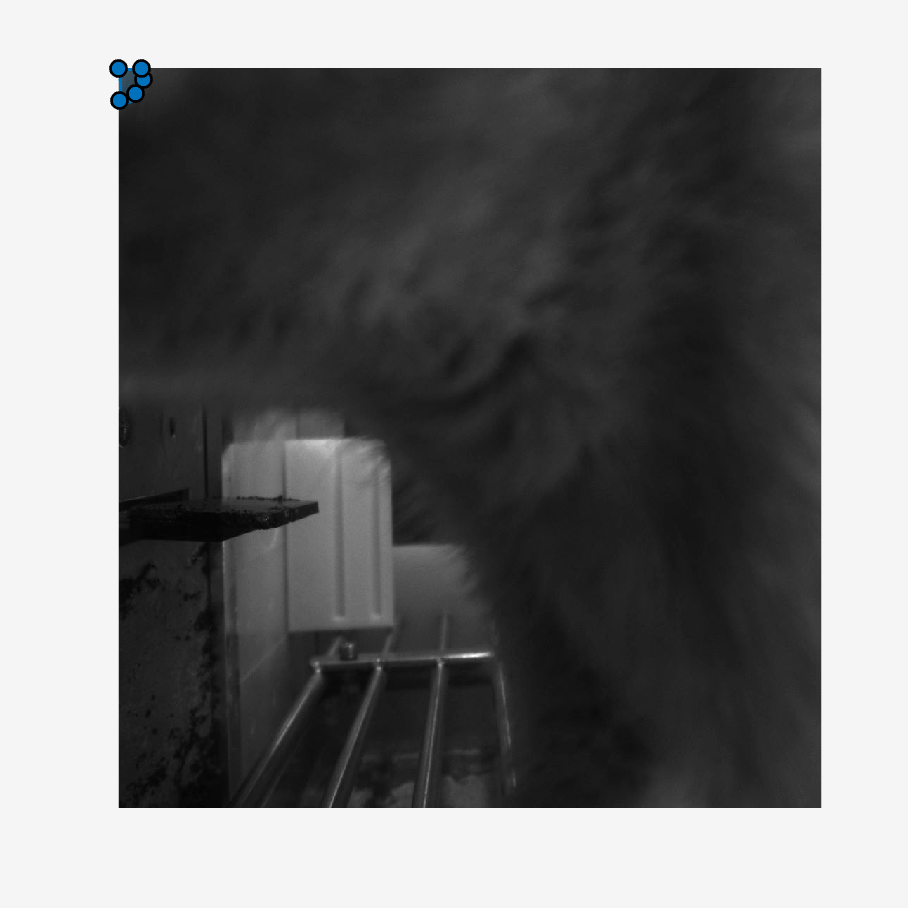

%%
% Get frame information and ROI time [384.00 384.10] 
t_sec               =       373;
framerate           =       10;
t_check             =       [0 5]+(t_sec)*100;
tic
% >>x=dir('*.seq')'
% >>arrayfun(@(x)x.name, x, 'UniformOutput', false)'
% ans =
%   6×1 cell 数组
%     {'20230318-16-35-02.000.seq'}
%     {'20230318-16-35-04.000.seq'}
%     {'20230318-16-56-53.000.seq'}
%     {'20230318-16-56-56.000.seq'}
%     {'20230318-17-17-14.000.seq'}
%     {'20230318-17-17-17.000.seq'}

% only choose ROI once
ind_start = length('SideView_')+1;
mask = ExtractMaskSeq([names{1}(ind_start:end) '.000.seq'], [3200 3200]+5*60*100);


for i =1:length(names)
    if  any(ismember(names{i}, 'Top'))% top view
        GetSeqFrameInfo(file_names(i), t_check, names{i}, 0);
    elseif any(ismember(names{i}, 'Side')) % side view
        GetSeqFrameInfo(file_names(i), t_check, names{i}, 1, mask);
    end
end

ans = 'Extracting ......'

ans = '60000 frames (~ 10min) extracted 10 '

ans = '60000 frames (~ 10min) extracted 20 '

ans = '60000 frames (~ 10min) extracted 30 '

历时 459.964174 秒。


ans = 'Extracting ......'

历时 26.036239 秒。


toc

历时 26.057350 秒。


## Step 2 | Align frames to behavior

### Gather trigger time from r

Look for r file

r_file = dir('RTarray*.mat')

r_file = 包含以下字段的 struct:
       name: 'RTarray_Maddy_20251127.mat'
     folder: '/Volumes/CY-SSD/Videos/Maddy/20251127'
       date: '12- 4-2026 01:30:46'
      bytes: 59031190
      isdir: 0
    datenum: 7.4008e+05


if ~isempty(r_file) && isscalar(r_file)
    load(r_file.name)
end
TriggerTime = Spikes.Videos.ExtractTrigger(r);% trigger time in seconds

### Gather LED onset time, and align it to Ephys' time

     1

   553   579

     2

         994        1020

     3

        1344        1370

     4

        1890        1916

     5

        2301        2327

     6

        2526        2552

     7

        2971        2997

     8

        3839        3865

     9

        5409        5435

    10

        5998        6024

    11

        6387        6413

    12

        6995        7021

    13

        7653        7680

    14

        9058        9085

    15

        9247        9274

    16

        9431        9458

    17

       10198       10225

    18

       10705       10732

    19

       11487       11513

    20

       11731       11757

    21

       12182       12208

    22

       12449       12475

    23

       12759       12785

    24

       13443       13469

    25

       15153       15179

    26

       15342       15368

    27

       15759       15785

    28

       16171       16197

    29

       16364       16390

    30

       16975      

#############################
######## Please wait ########
#############################


ans = 'check seqson 100 of 260'

ans = 'check seqson 200 of 260'

历时 3.172297 秒。


Define the threshold
Threshold defined
Define the threshold
Threshold defined
#############################
######### Done correcting #######
#############################


#############################
######## Please wait ########
#############################


ans = 'check seqson 100 of 261'

ans = 'check seqson 200 of 261'

历时 3.097496 秒。


     1

   370   397

     2

         983        1010

     3

        1483        1510

     4

        1677        1704

     5

        3770        3796

     6

        5490        5516

     7

        6252        6278

     8

        7617        7643

     9

        7881        7907

    10

        8365        8391

    11

       10242       10268

Select mulitple points to define a decision boundary, end selection by right click


#############################
######## Please wait ########
#############################
历时 0.136380 秒。


Define the threshold
Threshold defined
Define the threshold
Threshold defined
#############################
######### Done correcting #######
#############################


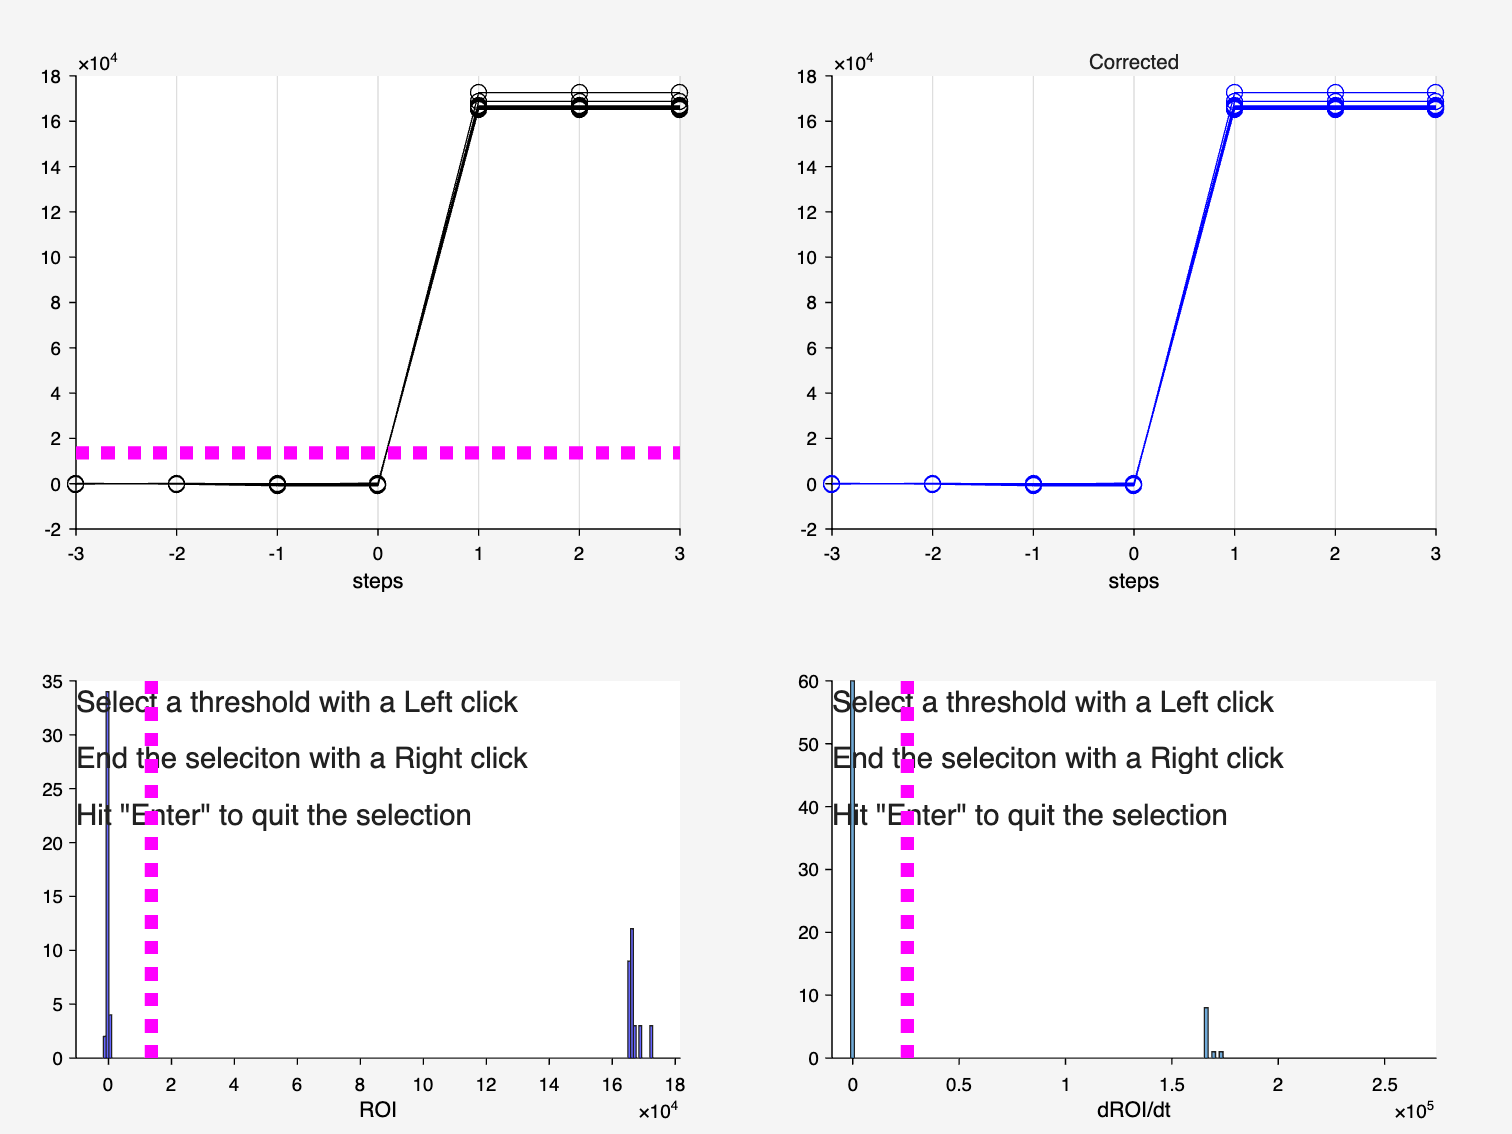

#############################
######## Please wait ########
#############################
历时 0.191739 秒。


fi_file = dir('FrameInfo*.mat');
FrameData = cell(length(fi_file)/2,2);
for i = 1:length(fi_file)
    fi_name = fi_file(i).name;
    FrameData{i} = fi_name;
end

nseg = size(FrameData, 1);
tLEDon = cell(1, nseg);

for i =1:nseg
    % load side view frame info
    side_info           =       load(FrameData{i, 1});
    top_info            =       load(FrameData{i, 2});
    % map LED to trigger time (blackrock), use orignal frame time for
    % better tracking across side and top videos 
    tFrames_side        =       side_info.FrameInfo.tframeOrg;
    tLEDon{i}           =       FindLEDonAuto(tFrames_side, side_info.FrameInfo.ROI, ['_Seg_' extractBefore(FrameData{i, 1}, '.mat')]); % in ms
    close(gcf)
    Indout              =       findseqmatchrev(TriggerTime*1000, tLEDon{i}, 0, 1);
    close(gcf)
    % these LEDon times are the ones that cannot be matched to trigger. It must be a false positive signal that was picked up by mistake in "tLEDon = FindLEDon(tsROI, SummedROI);"
    ind_badROI = find(isnan(Indout));
    tLEDon{i}(ind_badROI) = []; % remove them
    Indout(ind_badROI) = []; % at this point, each LEDon time can be mapped to a trigger time in b (Indout)

    % add information to FrameInfo (side)
    side_info.FrameInfo.tLEDon_ms = tLEDon{i};
    side_info.FrameInfo.Indout = Indout;
    side_info.FrameInfo.TriggerTimeEphys_ms = TriggerTime*1000;
    side_info.FrameInfo.tFramesMapped2Ephys_ms = MapVidFrameTimeToAnotherDomain(tLEDon{i},  TriggerTime(Indout)*1000, tFrames_side);

    % add information to FrameInfo (top)
    tFrames_top                                =       top_info.FrameInfo.tframeOrg;
    top_info.FrameInfo.tLEDon_ms               =       tLEDon{i};
    top_info.FrameInfo.tFramesMapped2Ephys_ms  =       MapVidFrameTimeToAnotherDomain(tLEDon{i},  TriggerTime(Indout)*1000, tFrames_top);

    %% Empirically, some events are still not well aligned. In particually, in a small subset of trials, LED starts to light up at trigger time we need to revise these trials.
    % some tLEDon need to be revised.
    imhappy = 0;
    while ~imhappy
        tLEDon_         =       CorrectLEDtimeEphysTriggerTime(side_info.FrameInfo);
        if length(tLEDon{i})==length(tLEDon_) & sum(abs(tLEDon{i}(:)-tLEDon_(:)))==0
            imhappy = 1;
        else
            Indout      =       findseqmatchrev(TriggerTime*1000, tLEDon_, 0, 1);
            close(gcf)
            % these LEDon times are the ones that cannot be matched to trigger. It must be a false positive signal that was picked up by mistake in "tLEDon = FindLEDon(tsROI, SummedROI);"
            ind_badROI = find(isnan(Indout));
            tLEDon{i}(ind_badROI) = []; % remove them
            Indout(ind_badROI) = []; % at this point, each LEDon time can be mapped to a trigger time in b (Indout)
            
            if length(tLEDon{i})~=length(tLEDon_)
                tLEDon{i} = tLEDon_;
            end

            % add information to FrameInfo (side)
            side_info.FrameInfo.tLEDon_ms = tLEDon_;
            side_info.FrameInfo.Indout = Indout;
            side_info.FrameInfo.tFramesMapped2Ephys_ms = MapVidFrameTimeToAnotherDomain(tLEDon_,  TriggerTime(Indout)*1000, tFrames_side);

            % add information to FrameInfo (top)
            tFrames_top                                =       top_info.FrameInfo.tframeOrg;
            top_info.FrameInfo.tLEDon_ms               =       tLEDon{i};
            top_info.FrameInfo.tFramesMapped2Ephys_ms  =       MapVidFrameTimeToAnotherDomain(tLEDon{i},  TriggerTime(Indout)*1000, tFrames_top);
            imhappy = 1;
        end
    end

    % save side view frame
    FrameInfo = side_info.FrameInfo;
    save(['Aligned_' FrameData{i, 1}], 'FrameInfo');
    FrameInfo = top_info.FrameInfo;
    save(['Aligned_' FrameData{i, 2}], 'FrameInfo');
end

## Step 3 | Make videos based on critical time

### Example 1 | Extract all frames corresponding to the moments when animal released the lever

Step2_MakeVideos_cy;

Saved: /Volumes/CY-SSD/Videos/Maddy/20251127/VideoClips/Retrieval/Top_Retrieval_51615_52467.mp4 (Duration: 7.99 s)
Saved: /Volumes/CY-SSD/Videos/Maddy/20251127/VideoClips/Retrieval/Top_Retrieval_66945_70183.mp4 (Duration: 1.21 s)
Saved: /Volumes/CY-SSD/Videos/Maddy/20251127/VideoClips/Retrieval/Top_Retrieval_76834_80718.mp4 (Duration: 1.32 s)
Saved: /Volumes/CY-SSD/Videos/Maddy/20251127/VideoClips/Retrieval/Top_Retrieval_89544_90417.mp4 (Duration: 0.42 s)
Saved: /Volumes/CY-SSD/Videos/Maddy/20251127/VideoClips/Retrieval/Top_Retrieval_140532_142716.mp4 (Duration: 0.82 s)
Saved: /Volumes/CY-SSD/Videos/Maddy/20251127/VideoClips/Retrieval/Top_Retrieval_147122_148129.mp4 (Duration: 0.43 s)
Saved: /Volumes/CY-SSD/Videos/Maddy/20251127/VideoClips/Retrieval/Top_Retrieval_195261_196545.mp4 (Duration: 0.50 s)
Saved: /Volumes/CY-SSD/Videos/Maddy/20251127/VideoClips/Retrieval/Top_Retrieval_228120_229225.mp4 (Duration: 0.45 s)
Saved: /Volumes/CY-SSD/Videos/Maddy/20251127/VideoClips/Retrieval/Top_Re

function names = ProduceNames(filenames, attachments);
    names = cell(1, length(filenames));
    for i =1:length(filenames)
        vidfile = extractBefore(filenames{i}, '.000.seq');
        names{i} = [attachments{i} '_' vidfile];
    end
end